## Testbed for Math Functions In C++

### Computing FFT

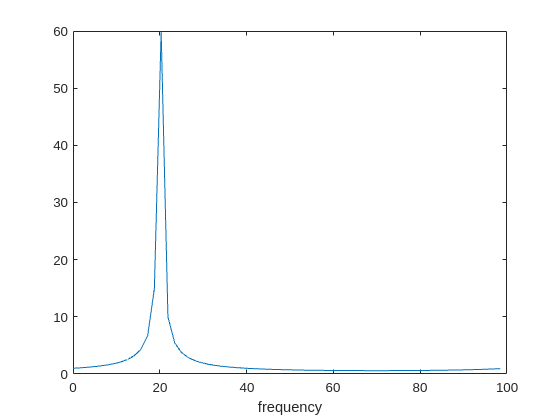

clear;
%generate a sample signal
    %specify N and sampling rate to generate a set of time values
    N = 64;
    Fs = 100;
    t = (0:1/Fs:(N/Fs - 1/Fs)).';

    %compute the complex signal
    F = 20; %Hz
    T = 1/F;
    f_t = exp(1j*2*pi* F * t);


%compute the fft
f = fft(f_t);

%plot the magnitude of the fft
freq_bins = (0:1/N:1-1/N) * Fs;
plot(freq_bins,abs(f))
xlabel("frequency");

%save the signal sample to a file
%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/sample_sinusoid.bin";
fileID = fopen(path,'w');
data = double(f_t);
data_to_export = reshape([real(data),imag(data)].',[],1);
fwrite(fileID,data_to_export, 'float32');
fclose(fileID);

%read the processed sample from the file
%to open a file from the GNU radio saved to a binary file
path = "/home/david/Documents/MATLAB_generated/computed_fft.bin";
fileID = fopen(path,'r');
read_data = fread(fileID,'float');

%convert to complex values
read_data = reshape(read_data,2,[]).';
read_data = read_data(:,1) + 1j * read_data(:,2);

%plot the magnitude of the processed fft to confirm it is correct
plot(freq_bins,abs(read_data))
xlabel("frequency");

## Computing Cross Correlation

clear;

%load the estimated and computed chirps from the saved workspace
estimated_chirp = load("estimated_chirp","estimated_chirp").estimated_chirp.';
computed_chirp = load("computed_chirp","computed_chirp").computed_chirp;

%set write path to save the estimated and computed chirps
estimated_chirp_path = "/home/david/Documents/BlackBoxRadarAttacks/CPP Development_Archive/cross_corr/estimated_chirp.bin";
computed_chirp_path = "/home/david/Documents/BlackBoxRadarAttacks/CPP Development_Archive/cross_corr/computed_chirp.bin";

%save the estimated and computed chirps to a file - for float
save_to_file(estimated_chirp,estimated_chirp_path,'float32')
save_to_file(computed_chirp,computed_chirp_path,'float32')

% %save the estimated and computed chirps to a file - for double
% save_to_file(estimated_chirp,estimated_chirp_path,'double')
% save_to_file(computed_chirp,computed_chirp_path,'double')

%get the result computed using cpp from the saved file
result_path = "/home/david/Documents/BlackBoxRadarAttacks/CPP Development_Archive/cross_corr/result.bin";
result = read_from_file(result_path,true,'float32');

FMCW_sample_rate_Msps = 29.536;

## Perform Cross Correlation in MATLAB and plot the result

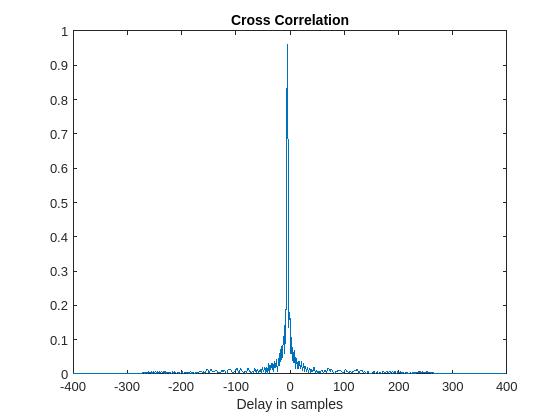

%perform cross correlation and convert into a timing offset
max_lag = 400;
[C,lag] = xcorr(estimated_chirp,computed_chirp,"normalized",max_lag);


%plot in matlab
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")


[M,I] = max(abs(C));
delay_samps_C = lag(I)

delay_samps_C = -5


delay_us_C = delay_samps_C / FMCW_sample_rate_Msps

delay_us_C = -0.1693


% 
% precise_start_time_samples = chirp_start_sample + delay_samps;
% precise_start_time = precise_start_time_samples / ...
%     obj.FMCW_sample_rate_Msps + obj.detection_start_time;

## Check result and plot

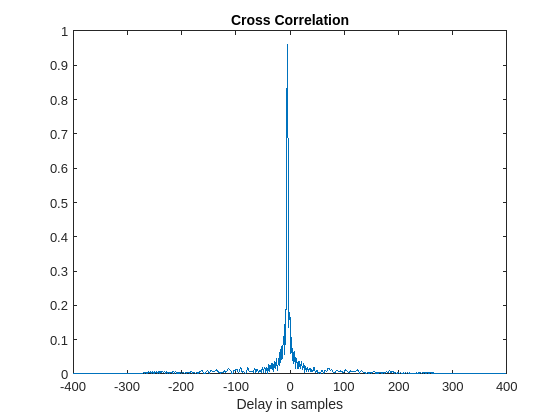

%plot in matlab
clf;
plot(lag,abs(result));
xlabel("Delay in samples")
title("Cross Correlation")


[M,I] = max(abs(result));
delay_samps_result = lag(I)

delay_samps_result = -5


delay_us_result = delay_samps_result / FMCW_sample_rate_Msps

delay_us_result = -0.1693


% 
% precise_start_time_samples = chirp_start_sample + delay_samps;
% precise_start_time = precise_start_time_samples / ...
%     obj.FMCW_sample_rate_Msps + obj.detection_start_time;

### Compare Computed Cross Correlation with one computed using cpp

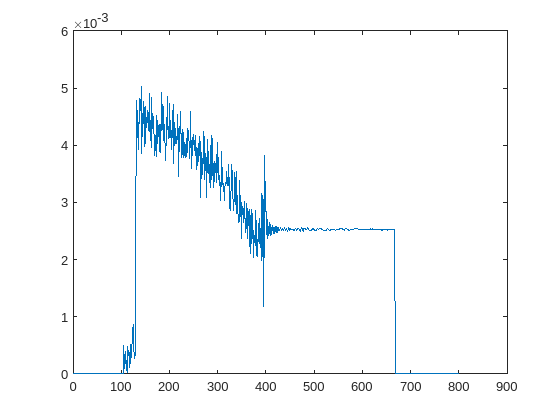

diff = abs(C - result);
plot(diff)

### Support Functions

function save_to_file(data_to_save,path,dtype)
    fileID = fopen(path,'w');
    data = double(data_to_save);
    fwrite(fileID,reshape([real(data),imag(data)].',[],1), dtype);
    fclose(fileID);
end

function read_data = read_from_file(path, complex_data, dtype)
    fileID = fopen(path,'r');
    read_data = fread(fileID,dtype);
    %read_data = fread(fileID,'float');
    
    %convert to complex values
    if complex_data
        read_data = reshape(read_data,2,[]).';
        read_data = read_data(:,1) + 1j * read_data(:,2);
    end
end